clear;
clc;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Vp=Lp*1*epssp;
Vn=Ln*1*epssn;

t_0=0.363;
F=96485.33289;

load comsol_data\ilocn.txt;
ilocn=ilocn(:,2);
mean(ilocn)

ans =        1.9164


load comsol_data\ilocp.txt;
ilocp=ilocp(:,2);
mean(ilocp)

ans =      -0.63815


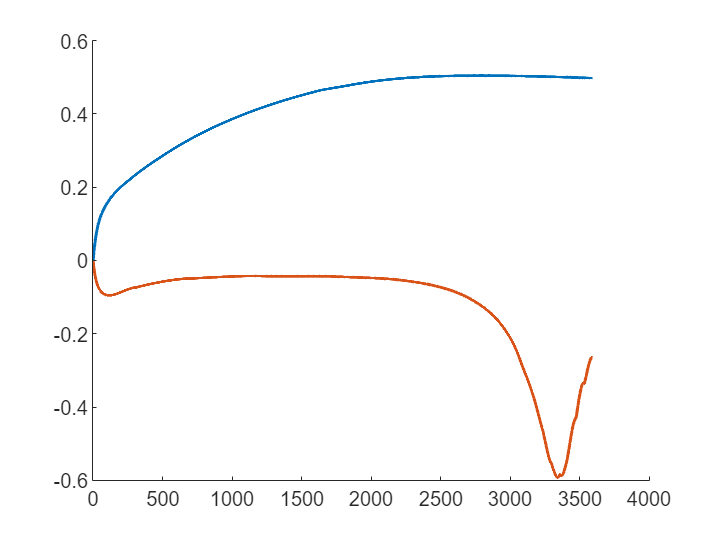

ap=3*epssp*Rsp;
an=3*epssn*Rsn;

ce_ilocp=ilocp/F/Vp;
ce_ilocn=ilocn/F/Vn;

figure(1);
clf;
hold on;
plot(ce_ilocn,LineWidth=1.5);
plot(ce_ilocp,LineWidth=1.5);

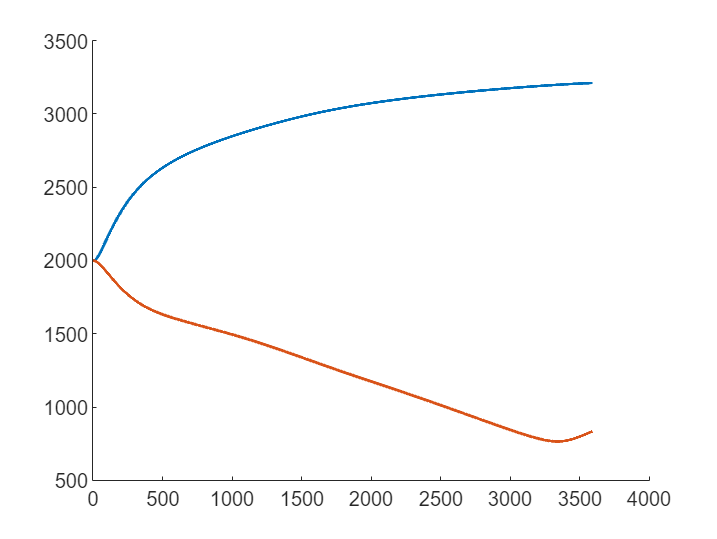


load comsol_data\cen_load.txt;
load comsol_data\cep_load.txt;
cen=cen_load(:,2);
cep=cep_load(:,2);
figure(2);
clf;
hold on;
plot(cen,LineWidth=1.5);
plot(cep,LineWidth=1.5);

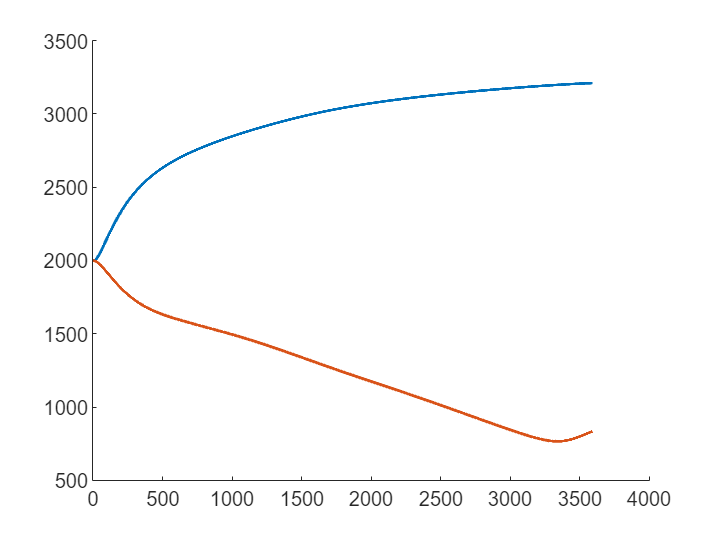

dcep=cep-ce_ilocp;
dcen=cen-ce_ilocn;

figure(3);
clf;
hold on;
plot(dcen,LineWidth=1.5);
plot(dcep,LineWidth=1.5);